# Dynamic simulation using complementarity methods (II)

Author: Jiayin Xie 

Date: August 19 2020

### File structure

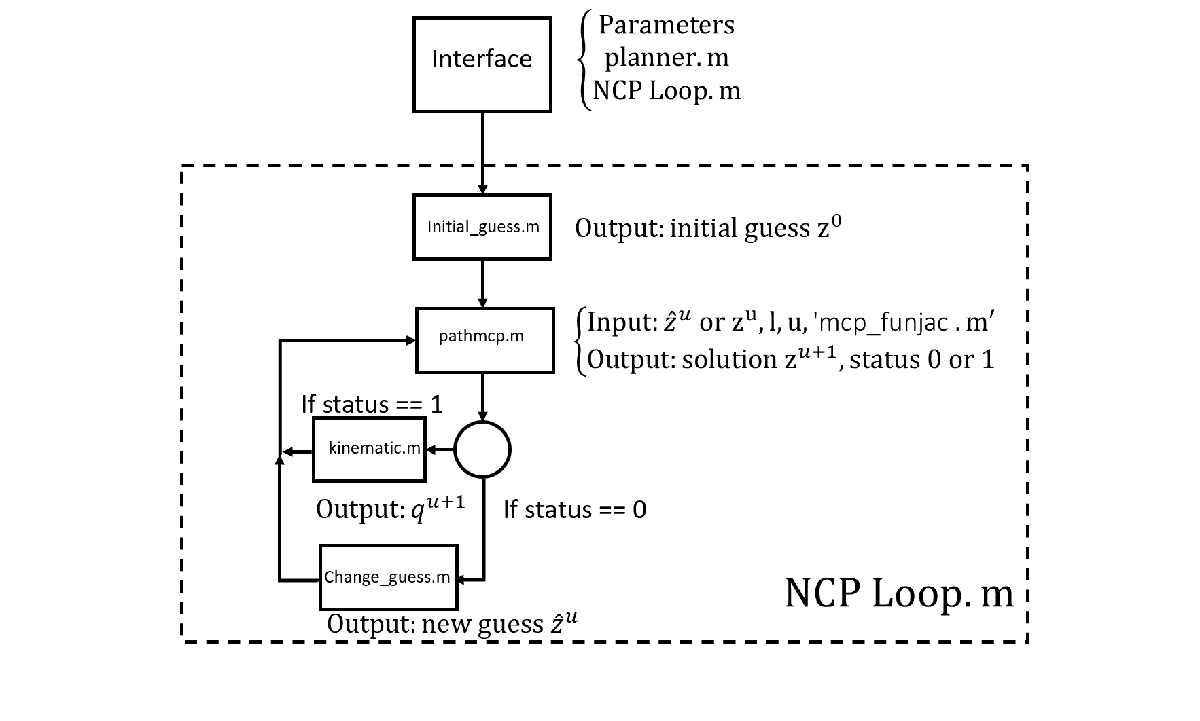

### Examples of a cube and ground

Interface script

%% notation
% l - beginning of current time step
% l+1 - end of current time step
% If the error 'Jacobian has too many entries: update nnz in pathmcp.m'
% appears , you can modify the mod_N parameter in pathmcp.m file

clear all
cd('..');
addpath('convex_contact_patches_interface');
addpath('visualize');
addpath('utility');
addpath('funjac');
addpath('pathmexmaci64');

cd('convex_contact_patches_interface')
A = struct();
A.object = 'cube';
% mass of the object
A.mass = 3; %(kg)
A.gravity = 9.8; %(m/s^2)

% approximate dimension of the object 
A.dim=[0.5 0.5 0.5]; %(m) length width height

% friction model
A.ellipsoid = [1 1 0.1]; % the choice of e_r (m) depends on the CM
A.cof = 0.22;

% time step
A.h = 0.01; %(s)

% initial state and configuration
A.initial_q = [0;0;2;1;0;0;0]; % m
A.initial_v = [0;0;0;1;3;1];  %m/s

% unit
A.unit = 1; % 1 - m, 10 - dm, 100 - cm, 1000 - mm  


% impulses
A = planner_cuboid(A);
%N - the number of iteration



A = NCP_cuboid(A);

%movie_cuboid(A);

### Examples of a cylinder and ground

%% notation
% l - beginning of current time step
% l+1 - end of current time step
% If the error 'Jacobian has too many entries: update nnz in pathmcp.m'
% appears , you can modify the mod_N parameter in pathmcp.m file

clear all
cd('..');
addpath('convex_contact_patches_interface');
addpath('visualize');
addpath('utility');
addpath('funjac');
addpath('pathmexmaci64');

cd('convex_contact_patches_interface')
A = struct();
A.object = 'cylinder';
% mass of the object
A.mass = 75; %(kg)
A.gravity = 9.8; %(m/s^2)

% approximate dimension of the object 
A.dim=[0.1 0.3]; %(m) radius height

% friction model
A.ellipsoid = [1 1 0.05]; % the choice of e_r (m) depends on the CM
A.cof = 0.8;

% time step
A.h = 0.01; %(s)

% initial state and configuration
A.initial_q = [0;0;A.dim(2)/2;1;0;0;0]; % m
%A.initial_q = [0;0;A.dim(1);cos(pi/4);sin(pi/4);0;0]; % m
A.initial_v = [0;0;0;0;0;0];  %m/s

% unit
A.unit = 1; % 1 - m, 10 - dm, 100 - cm, 1000 - mm  

% impulses
A = planner_cylinder(A);
%N - the number of iteration



A = NCP_cylinder(A);

%movie_cylinder(A);


### Appendix

clear all
%% define the symbolic variables
%% (1) unknown variables z
syms v_x v_y v_z w_x w_y w_z real; % velocity
nu =[v_x;v_y;v_z;w_x;w_y;w_z];
V = nu(1:3);
W = nu(4:6);
syms a1_x a1_y a1_z a2_x a2_y a2_z real % equivalent contact point
a1 = [a1_x;a1_y;a1_z];
a2 = [a2_x;a2_y;a2_z];

syms p_t p_o p_r p_n real; % frictional forces and moments

syms l1 l2 l3 l4 l5 l6 l7 real; % lagrangue multiplier for contact constraints 
L = [l1;l2;l3;l4;l5;l6;l7];

syms sig real; % lagrange multiplier for friction model

%% (2) inputs: old velocity and configurations and applied forces 

syms v_xo v_yo v_zo w_xo w_yo w_zo real;
nu_old = [v_xo;v_yo;v_zo;w_xo;w_yo;w_zo];

V_old = nu_old(1:3);

W_old = nu_old(4:6);


syms q_xo q_yo q_zo q0_o q1_o q2_o q3_o real;
q_old = [q_xo;q_yo;q_zo;q0_o;q1_o;q2_o;q3_o];

syms p_x p_y p_z p_xt p_yt p_zt real;
P_app = [p_x;p_y;p_z;p_xt;p_yt;p_zt];

%% (3) intermediate variables
syms q_x q_y q_z real;
q= [q_x;q_y;q_z];

syms q0 q1 q2 q3 real;

syms R11 R12 R13 R21 R22 R23 R31 R32 R33 real;
R = [R11 R12 R13;R21 R22 R23;R31 R32 R33];
 
syms I11 I12 I13 I21 I22 I23 I31 I32 I33 real;
Tensor_I = [I11 -I12 -I13;-I21 I22 -I23;-I31 -I32 I33];

%% (4) Parameters
syms h real; % time step h
syms g real; % gravity acceleration
syms m real;  %mass
M = [m,0,0;0,m,0;0,0,m];
syms mu real; % coefficient of friction 
syms e_t e_o e_r real; % parameters for friction ellipsoid
syms len wid heg real; % dimension of the cuboid

%% (5) coordinates in body frame
syms x y z real;
H(1:3,1:3) = R;
H(1:3,4) = q;
H(4,1:3)=0;
H(4,4) = 1;

P_w = [x;y;z;1];

H_i(1:3,1:3) = R';
H_i(1:3,4) = -R'*q;
H_i(4,1:3)=0;
H_i(4,4) = 1;
P_b = H_i*P_w;

%% unit wrenches
r = a1-q;

n = [0;0;1];
t = [1;0;0];
o = [0;1;0];

W_n(1:3,:) = sym(n);
W_n(4:6,:) = cross(r,n);

W_t(1:3,:) = sym(t);
W_t(4:6,:) = cross(r,t);

W_o(1:3,:) = sym(o);
W_o(4:6,:) = cross(r,o);

W_r(1:3,:) =  sym(0*n);
W_r(4:6,:) = sym(n);


%% Newton-Euler Equations


P_cont = W_n*p_n+W_t*p_t+W_o*p_o+W_r*p_r; % the net contact wrench

LHS(1:3,:)=M*(V-V_old)+[0;0;m*g*h]; % inertia forces
LHS(4:6,:)=Tensor_I*(W-W_old)+h*cross(W_old,Tensor_I*W_old); % inertia forces

RHS=P_cont + P_app; % applied forces

DYM = RHS - LHS;

%% friction model


P_friction(1,1)=mu*e_t^2*p_n*W_t'*nu+p_t*sig;
P_friction(2,1)=mu*e_o^2*p_n*W_o'*nu+p_o*sig;
P_friction(3,1)=mu*e_r^2*p_n*W_r'*nu+p_r*sig;

P_friction(4,1) = (mu*p_n)^2-(p_t/e_t)^2-(p_o/e_o)^2-(p_r/e_r)^2;

%% contact constraints 

gcn = z; % inequality for the horizontial plane

% equation of constraints (needs to be customized based on the scenario)
f_1 = -x-len/2;
f_2 =  x-len/2;
f_3 = -y-wid/2; 
f_4 =  y-wid/2;
f_5 = -z-heg/2;
f_6 =  z-heg/2;

N_l = 6; % number of constraints for object F
Fcn = [f_1;f_2;f_3;f_4;f_5;f_6];
Fcn = subs(Fcn,[x y z],[P_b(1) P_b(2) P_b(3)]);

sum_grad_a1 = 0;
for i = 1:N_l
    grad_a1(:,:,i) = gradient(Fcn(i),[x,y,z]);
    grad_a1(:,:,i) = subs(grad_a1(:,:,i),{x,y,z},{a1_x,a1_y,a1_z});
    sum_grad_a1 = sum_grad_a1 +L(i)*grad_a1(:,:,i);
end
sum_grad_a1 = simplify(sum_grad_a1); % conic combination of gradients for object F 

grad_a2 = [0;0;1];
lk = l7;

DST(1:3,1)=(a2-a1)+lk*(grad_a2);
DST(4:6,1)=grad_a2+sum_grad_a1;
DST(7:12,1) = -subs(Fcn,{x,y,z},{a1_x,a1_y,a1_z});
DST(13,1) = -subs(gcn,{x,y,z},{a2_x,a2_y,a2_z});  
DST(14,1) = subs(gcn,{x,y,z},{a1_x,a1_y,a1_z}); % nonpenetration constraints 

DST = simplify(DST);



fcn = [DYM;P_friction(1:3);DST(1:6);P_friction(4);DST(7:14)]; % the collections of all the equations
fcn = simplify(fcn);

% vecterize the unknown variables (needs to be customized based on the scenario)
Z(1,1:6) = [v_x v_y v_z w_x w_y w_z];
Z(1,7:12) = [a1_x a1_y a1_z a2_x a2_y a2_z];
Z(1,13:15) = [p_t p_o p_r];
Z(1,16) = sig;
Z(1,17:23) = [l1 l2 l3 l4 l5 l6 l7];
Z(1,24) = p_n;

% augmented variables for J1
T(1,1:24) = Z;
T(1,25:33) = [R11 R12 R13 R21 R22 R23 R31 R32 R33]; % the intermediate variables 
T(1,34:42) = [I11 I12 I13 I21 I22 I23 I31 I32 I33]; % the intermediate variables
T(1,43:45) = [q_x q_y q_z]; % the intermediate variables

% augmented variables for J2
U(1,1:24) = Z;
U(1,25:28) = [q0 q1 q2 q3];

J1 = jacobian(fcn',T);

J1 = simplify(J1);

T = subs(T,[R11 R12 R13 R21 R22 R23 R31 R32 R33 q_x q_y q_z],[q0^2 + q1^2 - q2^2 - q3^2, 2*q1*q2 - 2*q0*q3,2*q0*q2 + 2*q1*q3,2*q0*q3 + 2*q1*q2,q0^2 - q1^2 + q2^2 - q3^2,2*q2*q3 - 2*q0*q1,2*q1*q3 - 2*q0*q2,2*q0*q1 + 2*q2*q3,q0^2 - q1^2 - q2^2 + q3^2,q_xo+h*v_x,q_yo+h*v_y,q_zo+h*v_z]);
T = subs(T,I11,(I_xx*(q0^2 + q1^2 - q2^2 - q3^2)^2 + I_yy*(2*q0*q3 - 2*q1*q2)^2 + I_zz*(2*q0*q2 + 2*q1*q3)^2));
T = subs(T,I12,(I_xx*(2*q0*q3 + 2*q1*q2)*(q0^2 + q1^2 - q2^2 - q3^2) - I_zz*(2*q0*q1 - 2*q2*q3)*(2*q0*q2 + 2*q1*q3) - I_yy*(2*q0*q3 - 2*q1*q2)*(q0^2 - q1^2 + q2^2 - q3^2)));
T = subs(T,I13,I_zz*(2*q0*q2 + 2*q1*q3)*(q0^2 - q1^2 - q2^2 + q3^2) - I_xx*(2*q0*q2 - 2*q1*q3)*(q0^2 + q1^2 - q2^2 - q3^2) - I_yy*(2*q0*q1 + 2*q2*q3)*(2*q0*q3 - 2*q1*q2));
T = subs(T,I21,I_xx*(2*q0*q3 + 2*q1*q2)*(q0^2 + q1^2 - q2^2 - q3^2) - I_zz*(2*q0*q1 - 2*q2*q3)*(2*q0*q2 + 2*q1*q3) - I_yy*(2*q0*q3 - 2*q1*q2)*(q0^2 - q1^2 + q2^2 - q3^2));
T = subs(T,I22,I_yy*(q0^2 - q1^2 + q2^2 - q3^2)^2 + I_xx*(2*q0*q3 + 2*q1*q2)^2 + I_zz*(2*q0*q1 - 2*q2*q3)^2);
T = subs(T,I23,I_yy*(2*q0*q1 + 2*q2*q3)*(q0^2 - q1^2 + q2^2 - q3^2) - I_xx*(2*q0*q2 - 2*q1*q3)*(2*q0*q3 + 2*q1*q2) - I_zz*(2*q0*q1 - 2*q2*q3)*(q0^2 - q1^2 - q2^2 + q3^2));
T = subs(T,I31,I_zz*(2*q0*q2 + 2*q1*q3)*(q0^2 - q1^2 - q2^2 + q3^2) - I_xx*(2*q0*q2 - 2*q1*q3)*(q0^2 + q1^2 - q2^2 - q3^2) - I_yy*(2*q0*q1 + 2*q2*q3)*(2*q0*q3 - 2*q1*q2));
T = subs(T,I32,I_yy*(2*q0*q1 + 2*q2*q3)*(q0^2 - q1^2 + q2^2 - q3^2) - I_xx*(2*q0*q2 - 2*q1*q3)*(2*q0*q3 + 2*q1*q2) - I_zz*(2*q0*q1 - 2*q2*q3)*(q0^2 - q1^2 - q2^2 + q3^2));
T = subs(T,I33,I_zz*(q0^2 - q1^2 - q2^2 + q3^2)^2 + I_xx*(2*q0*q2 - 2*q1*q3)^2 + I_yy*(2*q0*q1 + 2*q2*q3)^2);

J2 = jacobian(T,U);
J2 =simplify(J2);

U= subs(U,[q0 q1 q2 q3],[-(2*((h*q1_o*w_x)/2 - q0_o + (h*q2_o*w_y)/2 + (h*q3_o*w_z)/2))/(h^2*w_x^2 + h^2*w_y^2 + h^2*w_z^2 + 4)^(1/2),(2*(q1_o + (h*q0_o*w_x)/2 + (h*q3_o*w_y)/2 - (h*q2_o*w_z)/2))/(h^2*w_x^2 + h^2*w_y^2 + h^2*w_z^2 + 4)^(1/2),(2*(q2_o - (h*q3_o*w_x)/2 + (h*q0_o*w_y)/2 + (h*q1_o*w_z)/2))/(h^2*w_x^2 + h^2*w_y^2 + h^2*w_z^2 + 4)^(1/2),(2*(q3_o + (h*q2_o*w_x)/2 - (h*q1_o*w_y)/2 + (h*q0_o*w_z)/2))/(h^2*w_x^2 + h^2*w_y^2 + h^2*w_z^2 + 4)^(1/2)]);
J3 = jacobian(U,Z);
J3 =simplify(J3);